# Estimating Coverage Including Propagation Effects

L = design(linearArray, 2e9, patchMicrostrip)

L =   linearArray with properties:

           Element: [1×1 patchMicrostrip]
       NumElements: 2
    ElementSpacing: 0.074948114500000
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


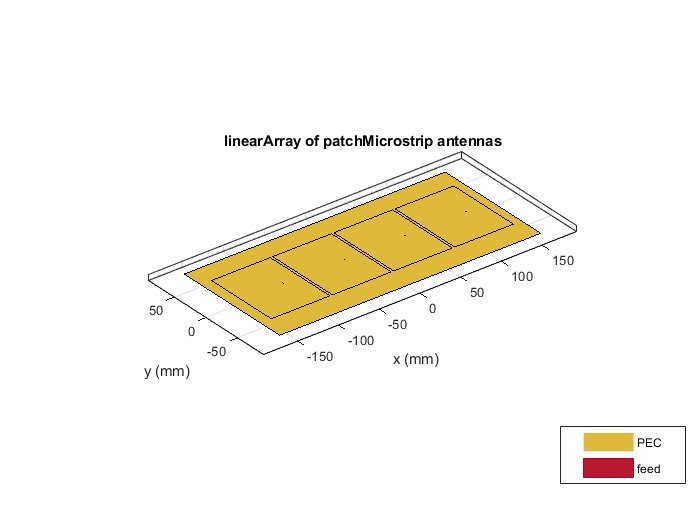

L.NumElements = 4;
L.Element.GroundPlaneLength = 80e-3;
show(L)

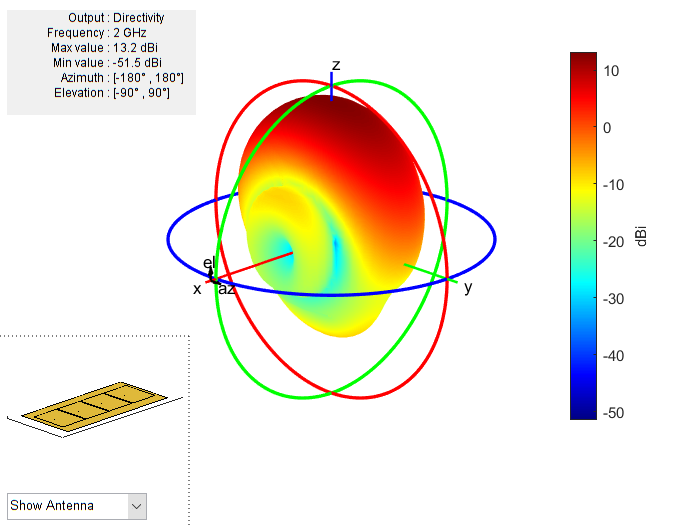

pattern(L, 2e9)

Position the transmitter and show the antenna array pattern.

tx = txsite('Name','Taipei_101',...
    'Latitude',25.033710, ...
    'Longitude',121.564718, ...
    'Antenna',L,...
    'AntennaHeight', 10, ...
    'AntennaAngle', [0; -90], ...
    'TransmitterFrequency',2e9,...
    'TransmitterPower',1);
pattern(tx,2e9)

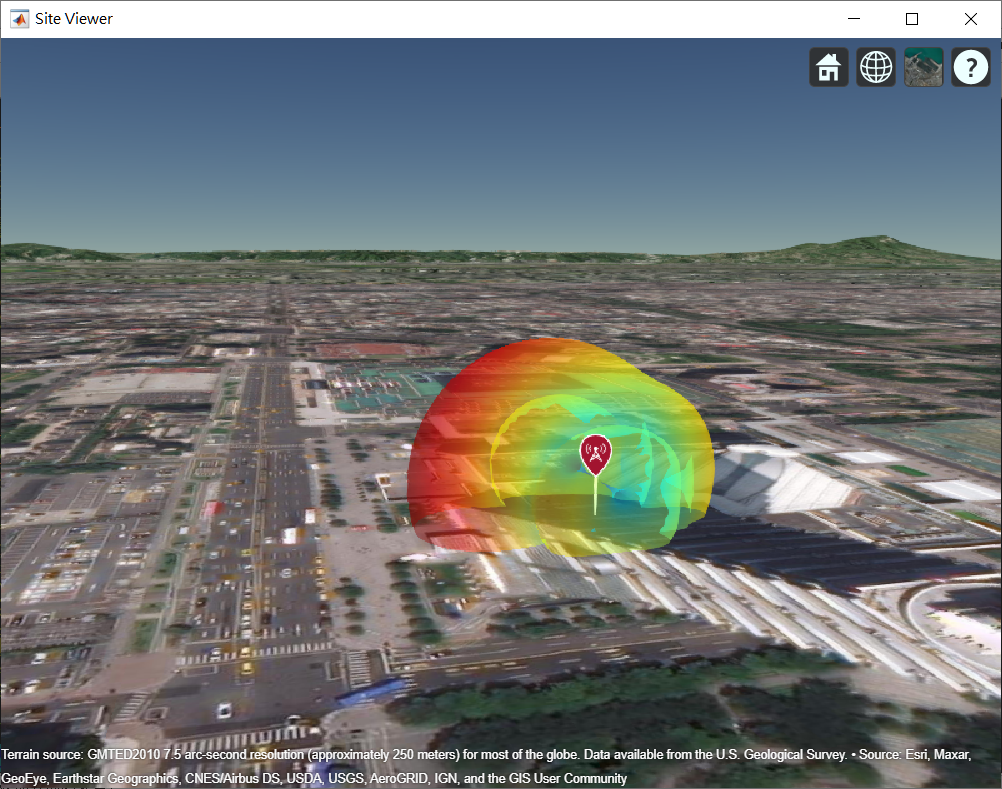

coverage(tx, 'longley-rice')

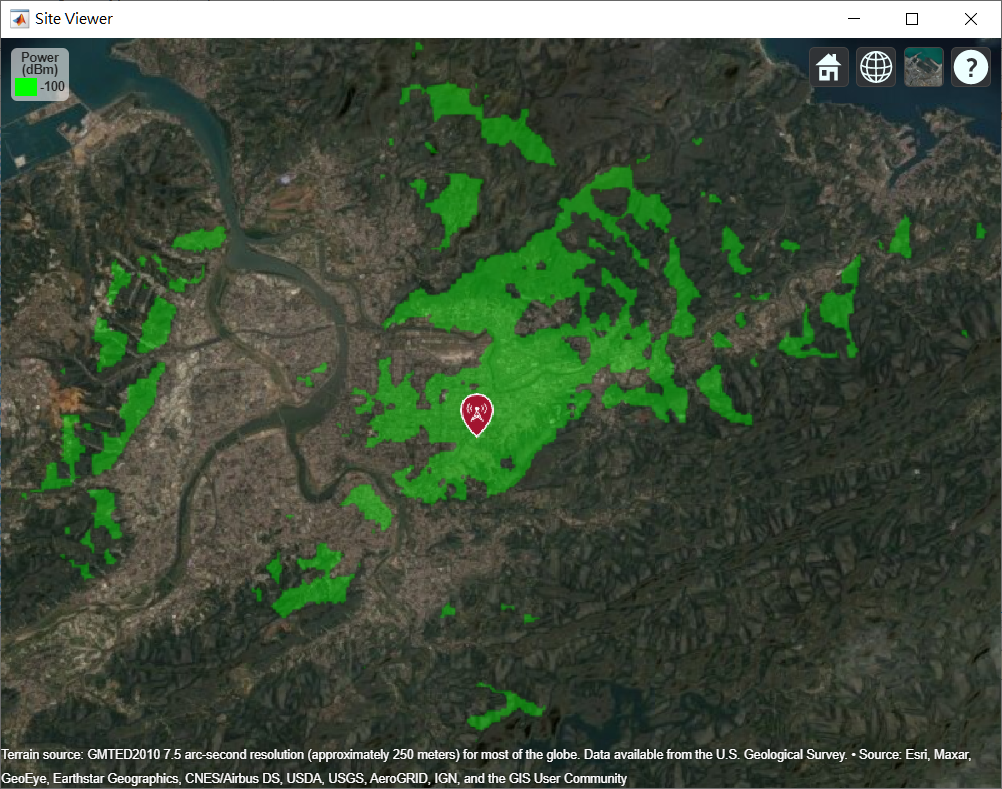

Position the transmitter and show the antenna array pattern.

rx = rxsite('Name','Receiver',...
    'Latitude',25.0279122079191, ...
    'Longitude',121.57077613085784, ...
    'Antenna',design(dipole, 2e9),...
    'AntennaHeight', 1.5,...
    'ReceiverSensitivity', -100 );
link(rx,tx)

rx = rxsite('Name','Zoo',...
    'Latitude',25.000230283187346, ...
    'Longitude',121.58069101763158, ...
    'Antenna',design(dipole, 2e9),...
    'AntennaHeight', 1.5,...
    'ReceiverSensitivity', -100 );
link(rx,tx)